Consider the IVP given by$y''' + 2y'' - y' - 2y = e^{x}, \quad y(0) = 1,\; y'(0) = 2,\; y''(0) = 0,\quad x\in[0,3]$

disp("IVP")
function dy = f1(t,y)
dy = [y(2); y(3); -2*y(3)+y(2)+2*y(1)+exp(t)];
end

a = 0;
b = 3;
iv = [1;2;0];

[x, y1] = Euler(@f1,a,b, iv)

x =          0    0.3000    0.6000    0.9000    1.2000    1.5000    1.8000    2.1000    2.4000    2.7000    3.0000


y1 =     1.0000    2.0000         0
    1.6000    2.0000    1.5000
    2.2000    2.4500    2.5650
    2.9350    3.2195    3.6276
    3.9008    4.3078    4.9158
    5.1932    5.7825    6.5952
    6.9279    7.7611    8.8332
    9.2562   10.4110   11.8333
   12.3796   13.9610   15.8602
   16.5679   18.7191   21.2671


[x, y2] = Heun(@f1,a,b, iv)

x =          0    0.3000    0.6000    0.9000    1.2000    1.5000    1.8000    2.1000    2.4000    2.7000    3.0000


y2 =     1.0000    2.0000         0
    1.6000    2.2250    1.2825
    2.3252    2.7992    2.4954
    3.2773    3.7404    3.8542
    4.5728    5.1238    5.5531
    6.3599    7.0815    7.7998
    8.8353    9.8122   10.8468
   12.2670   13.5989   15.0216
   17.0227   18.8369   20.7638
   23.6081   26.0731   28.6713


[x, y3] = RungeKutta(@f1,a,b, iv)

x =          0    0.3000    0.6000    0.9000    1.2000    1.5000    1.8000    2.1000    2.4000    2.7000    3.0000


y3 =     1.0000    2.0000         0
    1.6208    2.2079    1.3383
    2.3616    2.7932    2.5667
    3.3346    3.7622    3.9336
    4.6642    5.1882    5.6498
    6.5066    7.2083    7.9342
    9.0691   10.0309   11.0496
   12.6346   13.9540   15.3374
   17.5925   19.3946   21.2570
   24.4800   26.9314   29.4355


[x, y4] = AdamsBashforth(@f1,a,b, iv)

x =          0    0.3000    0.6000    0.9000    1.2000    1.5000    1.8000    2.1000    2.4000    2.7000    3.0000


y4 =     1.0000    2.0000         0
    1.6000    2.2250    1.2825
    2.3013    2.8021    2.4269
    3.2285    3.7019    3.7632
    4.4740    5.0313    5.3987
    6.1828    6.8962    7.5608
    8.5314    9.4887   10.4653
   11.7669   13.0640   14.4238
   16.2224   17.9849   19.8356
   22.3560   24.7474   27.2499


[x, y5] = MilneSimpson(@f1,a,b, iv)

x =          0    0.3000    0.6000    0.9000    1.2000    1.5000    1.8000    2.1000    2.4000    2.7000    3.0000


y5 =     1.0000    2.0000         0
    1.6208    2.2079    1.3383
    2.3616    2.7932    2.5667
    3.3346    3.7622    3.9336
    4.6649    5.1868    5.6526
    6.5065    7.2084    7.9341
    9.0696   10.0299   11.0517
   12.6345   13.9542   15.3370
   17.5925   19.3945   21.2573
   24.4798   26.9319   29.4346


[x, y6] = MilneTrap(@f1,a,b, iv)

x =          0    0.3000    0.6000    0.9000    1.2000    1.5000    1.8000    2.1000    2.4000    2.7000    3.0000


y6 =     1.0000    2.0000         0
    1.6000    2.2250    1.2825
    2.3252    2.7992    2.4954
    3.2773    3.7404    3.8542
    4.4550    5.3224    5.1139
    6.1752    7.4194    7.1272
    8.6479   10.2030   10.2022
   12.0802   14.0814   14.4236
   16.8346   19.4315   20.2526
   23.4648   26.7535   28.4496


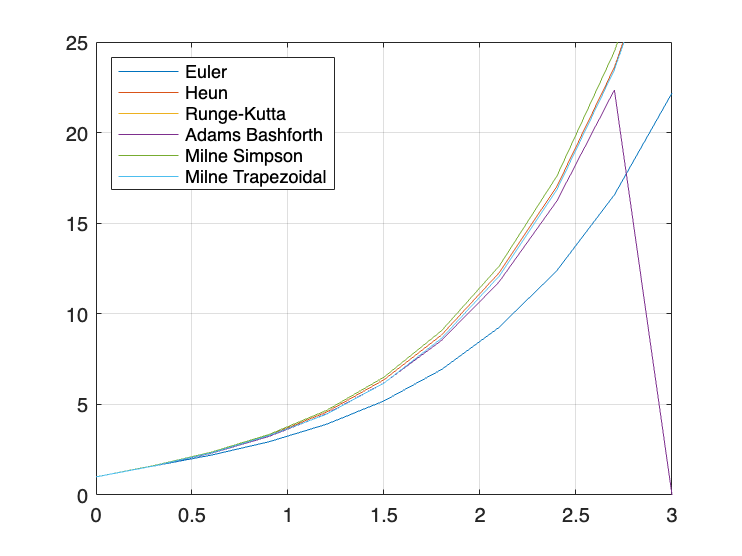


plot(x,y1(:,1))
hold on
plot(x,y2(:,1))
plot(x,y3(:,1))
plot(x,y4(:,1))
plot(x,y5(:,1))
plot(x,y6(:,1))
hold off
grid
legend("Euler","Heun","Runge-Kutta","Adams Bashforth","Milne Simpson","Milne Trapezoidal","Location","northwest")
ylim([0 25])

This solvers return 3 columns for this third order problem, being those the function at the nodes, as well as the first and second derivatives.

Consider the second order BVP given by


$$y'' + \frac{2}{x} y' - \frac{2}{x^2} y = 3x,y(1) = 1, y(2) = 4 \quad x \in [1, 2]$$



$$y'' + p(x) y' + q(x) y = r(x)$$


disp("BVP")
p = @(x) 2./x;
q = @(x) -2./(x.^2);
r = @(x) 3*x;

a = 1;
b = 2;

bc = [1,4];

[x, y1] = FiniteDifferences(p, q, r, a, b, bc)

x =     1.0000
    1.1000
    1.2000
    1.3000
    1.4000
    1.5000
    1.6000
    1.7000
    1.8000
    1.9000


y1 =     1.0000
    1.0606
    1.1504
    1.2784
    1.4535
    1.6848
    1.9814
    2.3522
    2.8062
    3.3525


[x, y2] = LinearShooting(p, q, r, a, b, bc)

x =     1.0000
    1.1000
    1.2000
    1.3000
    1.4000
    1.5000
    1.6000
    1.7000
    1.8000
    1.9000


y2 =     1.0000
    1.2006
    1.4162
    1.6500
    1.9049
    2.1831
    2.4870
    2.8186
    3.1800
    3.5732


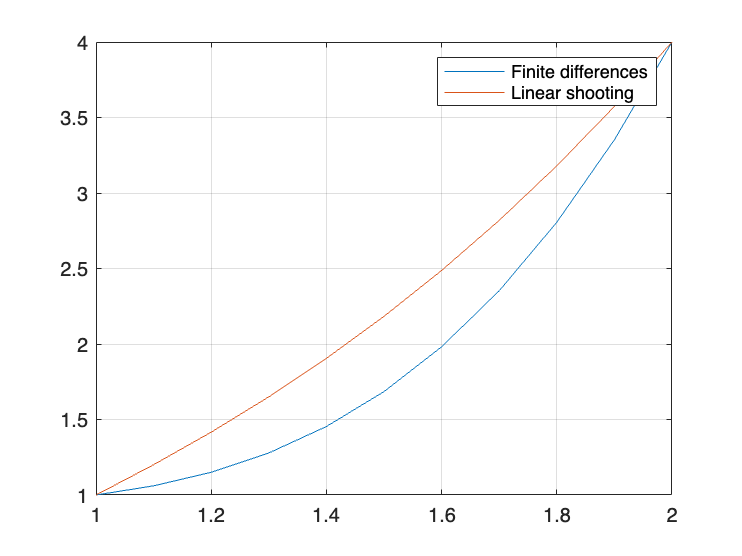


plot(x,y1)
hold on
plot(x,y2)
hold off

grid
legend("Finite differences", "Linear shooting")

Consider the BVP given by


$$y'' + \frac{1}{8} y \, y' = 4 + \frac{x^3}{4},\quad y(1)=17,y(3)=\frac{43}{3},\quad x\in[1,3]$$


By considering both the problem and its variational equations, the following formulation is obtained.

function dy = f2(x,y)
dy = [y(2); 
    1/8*(32+2*x.^3-y(1).*y(2));
    y(4);
    -1/8*y(2).*y(3)-1/8*y(1).*y(4)];
end

a = 1;
b = 3;
bc = [17; 43/3];

[x, y1, t1, iter1, dif1] = NonlinearShootingNewton(@f2, a, b, bc);
[x, y2, t2, iter2, dif2] = NonlinearShootingSecant(@f2, a, b, bc);
y1(:,1),iter1,dif1

ans =    17.0000
   14.7733
   13.3886
   12.5600
   12.1289
   12.0000
   12.1127
   12.4267
   12.9139
   13.5543


iter1 = 5

dif1 = 5.7292e-10

y2(:,1),iter2,dif2

ans =    17.0000
   14.7733
   13.3886
   12.5600
   12.1289
   12.0000
   12.1127
   12.4267
   12.9139
   13.5543


iter2 = 6

dif2 = 6.0442e-08

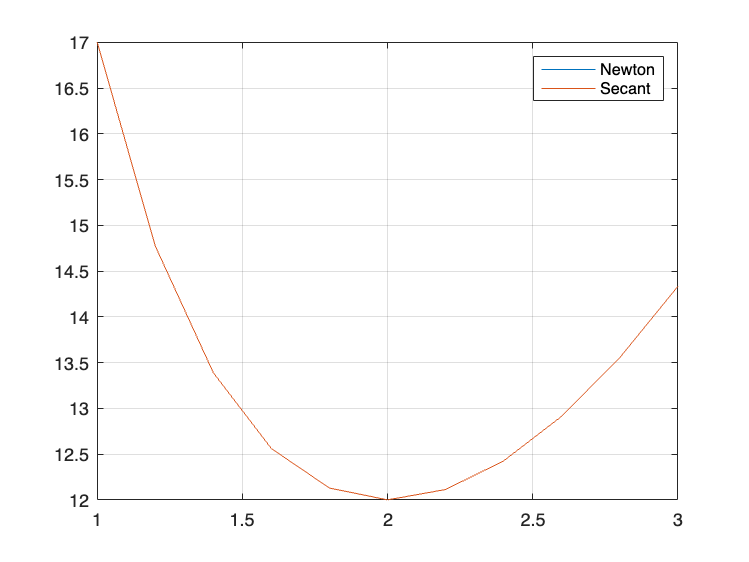


plot(x,y1(:,1))
hold on
plot(x,y2(:,1))
hold off

grid
legend("Newton", "Secant")

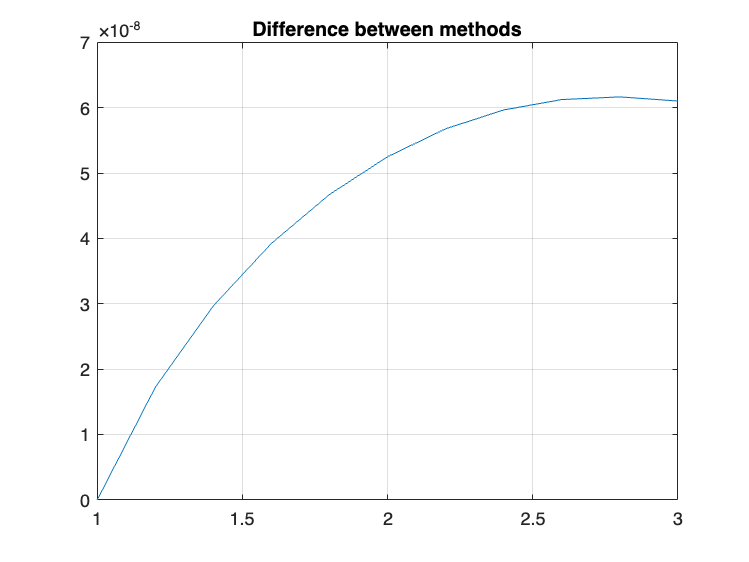



plot(x, abs(y1(:,1)-y2(:,1)))
grid
title("Difference between methods")